%页码：P86
%作者；暴富
%时间：2024-07-24
%项目：example3.7 
% OPFB具有邻域控制器和本地观测器信息，实现的轨迹追踪
%控制器的构造用了领域的信息差，观察器的构造用了本身信息

clc
clear
lineStyles = linspecer(7); % 指定线型颜色,一页有几条线

%%状态初始化
m1 = 1.1;
m2 = 0.9;
k1 = 1.5;
k2 = 1;
c = 2;
A = [0,1,0,0;...
    (-k1-k2)/m1 0 k2/m1 0;...
    0 0 0 1;...
    k2/m2 0 -k2/m2 0];
B = [0;1/m1;0;0];
C = [1 0 0 0;...
    0 0 1 0];

%%拓扑结构初始化
%这里用Aij代表邻接矩阵
Aij = [0 0 0 0 0 0;...
    2 0 0 0 0 0;...
    0 6 0 0 0 0;...
    0 0 1 0 0 0;...
    0 0 0 1 0 0;...
    0 0 0 0 3 0];
L = diag(sum(Aij,2)) - Aij;
G = diag([1,0,0,0,0,0]);

%%计算控制器增益，即反馈矩阵K
%stabilizable稳定性分析，转化为可控性分析
Ro = obsv(A,C);
rank(Ro); %ans = 4结果可控
Q1 = eye(4); %想要收敛快点就增大对角值
Q2 = diag([10,10,10,10]);
%观测器的收敛速度要比控制器快，这样保证估计的状态能保持在一个相对准确的状态
R = 1;
[F,P1] = lqr(A',C',Q2,R) ;
F = -F';%%根据定理3得知要加负号
[K,P2] = lqr(A,B,Q1,R) ;

%%仿真初始化
Ts = 0.01;
t = 0:Ts:25;
N = length(t);
%%agent初始化,7个agent，一个agent4个状态，每一页对应状态迭代
%real对应实际值，obv对应观测器
X_Real = zeros(4,6,N);
X_obv  = zeros(4,6,N);
X0_Real = zeros(4,1,N);
X0_obv  = zeros(4,1,N);

%设置随机状态
%6个智能体实际值
X_Real_initial = randn(4,6);
X_Real(:,:,1) = X_Real_initial;
%6个agent观测器初始值
X_obv_initial = randn(4,6);
X_obv(:,:,1) = X_obv_initial;
%领导者的实际值
X0_Real_initial = randn(4,1);
X0_Real(:,:,1) = X0_Real_initial;
%领导者观测器的初始值，leader 可以知道自己的状态
X0_obv(:,:,1) =  X0_Real(:,:,1);

## **原始系统**

**1.跟随者**

$$
\dot{x}_{i}=Ax_{i}+cBK\Bigg(\sum_{j\in N_{i}}a_{ij}(\hat{x}_{j}-\hat{x}_{i})+g_{i}(\hat{x}_{0}-\hat{x}_{i})\Bigg)
$$闭环系统

$$$
\dot{\hat{x}}_i=A\hat{x}_i+cBK\Bigg(\sum_{j\in N_{i}}a_{ij}(\hat{x}_{j}-\hat{x}_{i})+g_{i}(\hat{x}_{0}-\hat{x}_{i})\Bigg)-cF(y_i-\hat{y}_i)
$$$观测器

其中$$$
\hat{y}_i = C\hat{x}_i
$$$

### 2.领导者：

$$$
\dot{x}_0\,\,=\,\,Ax_0
$$
$，$$$
y_0=\hat{y}_0
$$
$；

## **离散后**

### **1.跟随者**


$$x_{i}(k+1) = x_{i}(k) + T_s \Bigg(Ax_{i}(k)+cBK\Bigg(\sum_{j\in N_{i}}a_{ij}(\hat{x}_{j}(k)-\hat{x}_{i}(k))+g_{i}(\hat{x}_{0}(k)-\hat{x}_{i}(k))\Bigg)\Bigg)
$$



$$$$
\hat{x}_i(k+1) = \hat{x}_i(k) + T_s\Bigg(A\hat{x}_i(k) +cBK\Bigg(\sum_{j\in N_{i}}a_{ij}(\hat{x}_{j}(k)-\hat{x}_{i}(k))+g_{i}(\hat{x}_{0}(k)-\hat{x}_{i}(k))\Bigg)-cF(y_i(k)-\hat{y}_i(k))
$$$$


### 2.领导者：


$$$$
\dot{x}_0(k)\,\,=\,\,Ax_0(k)
$$
$$


$$$
y_0(k)=\hat{y}_0(k)
$$
$；

# 考虑以下定义：

定义$$
sum\_xstate =\sum_{j\in N_i}a_{ij}(\hat{x}_{j}(k)-\hat{x}_{i}(k))
$$;


$$G\_term1 = g_{i}(\hat{x}_{0}(k)-\hat{x}_{i}(k))$$


# 整理的：

### **1.跟随者**


$$x_{i}(k+1) = x_{i}(k) + T_s \Bigg(Ax_{i}(k)+cBK*[sum\_xstate+G\_team1]\Bigg)$$



$$\hat{x}_i(k+1) = \hat{x}_i(k) + T_s\Bigg(A\hat{x}_i(k) +cBK*[sum\_xstate+G\_team1]-cF*C(x_i- \hat{x}_i)\Bigg)$$


### 2.领导者：


$$$$
\dot{x}_0(k)\,\,=\,\,Ax_0(k)
$$
$$


$$$
y_0(k)=\hat{y}_0(k)
$$
$；

## 拓扑结构

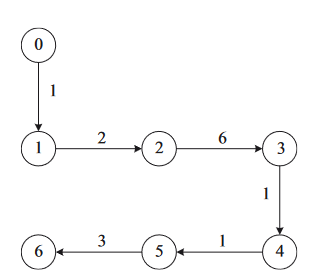

## 编程思维

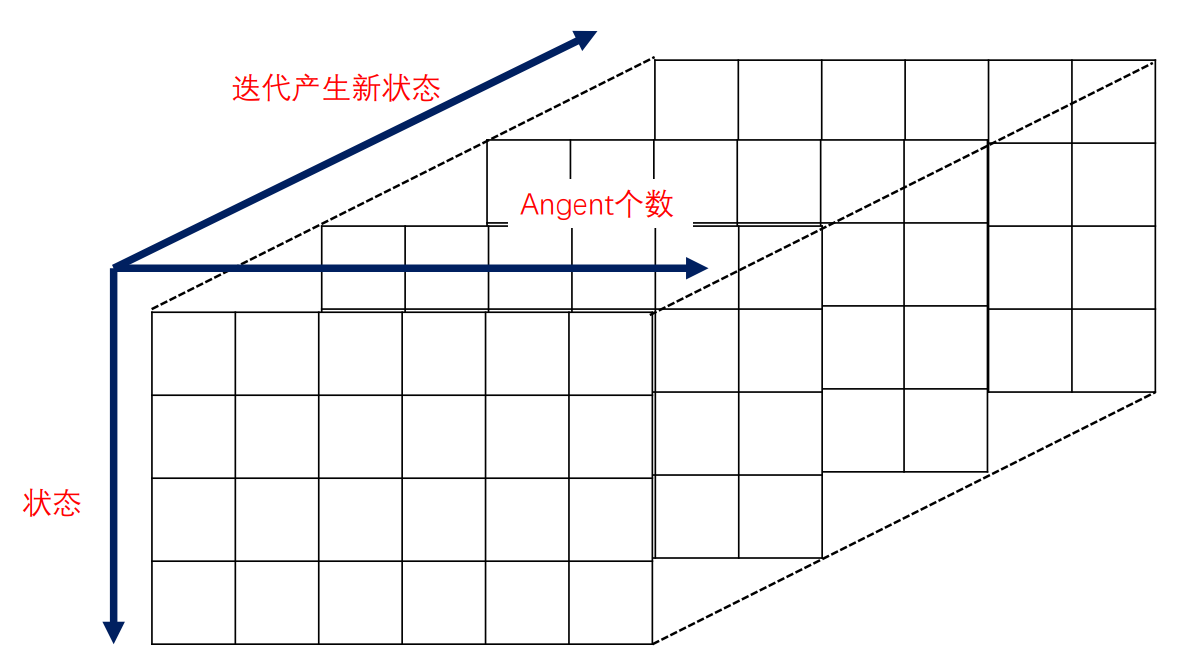

for k = 2:N
     %leader状态
     X0_Real(:,1,k) = X0_Real(:,1,k-1) + Ts*(A*X0_Real(:,1,k-1));
     X0_obv(:,1,k) = X0_Real(:,1,k); % leader 可以知道自己的状态
     for i = 1:6
         sum_xstate = 0;
         G_term1 = G(i,i)*(X0_obv(:,1,k-1)-X_obv(:,i,k-1));
         for j = 1:6
             sum_xstate = sum_xstate + Aij(i,j)*(X_obv(:,j,k-1)-X_obv(:,i,k-1));
         end
         X_Real(:,i,k) = X_Real(:,i,k-1) + Ts*(A*X_Real(:,i,k-1) + c*B*K*(sum_xstate+G_term1));
         X_obv(:,i,k)  = X_obv(:,i,k-1) + Ts*(A*X_obv(:,i,k-1)+c*B*K*(sum_xstate+G_term1) - c*F*C*(X_Real(:,i,k-1) - X_obv(:,i,k-1)));
     end
    
end


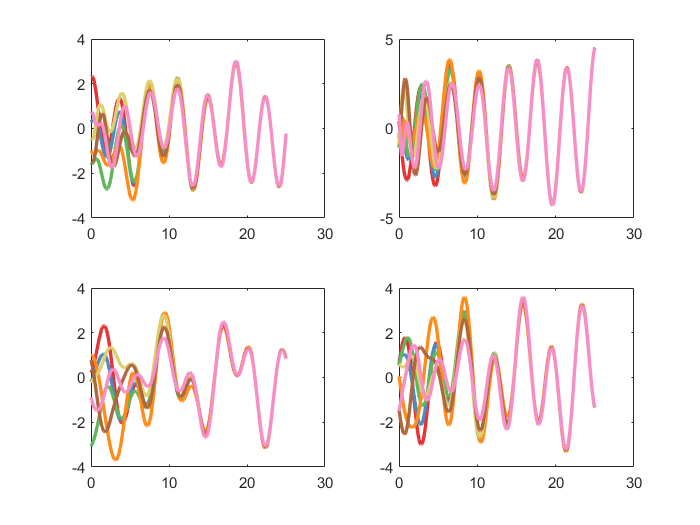

%%绘图:状态对应一直即可，x_1对x_1,x_2对x_2，x_2对x_2，x_2对x_2
%% 绘制结果
hf = figure;  %新建 图形控制句柄
hf.Color= [1 1 1]; % 控制图形的整体颜色。（scope中被默认为灰黑色，此处修改为白色）
xlim([0.0 25.0])
ylim([-3 3])

subplot(2,2,1)

plot(t,reshape(X0_Real(1,1,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on

%实际值
plot(t,reshape(X_Real(1,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(1,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(1,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(1,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(1,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(1,6,:),1,N),'Color',lineStyles(7,:),'linestyle','-','linewidth',2); 
% %观测器值
% plot(t,reshape(X0_obv(1,1,:),1,N),'Color',lineStyles(8,:),'linestyle','-','linewidth',2);
% plot(t,reshape(X_obv(1,1,:),1,N),'Color',lineStyles(9,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(1,2,:),1,N),'Color',lineStyles(10,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(1,3,:),1,N),'Color',lineStyles(11,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(1,4,:),1,N),'Color',lineStyles(12,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(1,5,:),1,N),'Color',lineStyles(13,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(1,6,:),1,N),'Color',lineStyles(14,:),'linestyle','-','linewidth',2); 

subplot(2,2,2)

plot(t,reshape(X0_Real(2,1,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on

%实际值
plot(t,reshape(X_Real(2,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(2,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(2,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(2,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(2,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(2,6,:),1,N),'Color',lineStyles(7,:),'linestyle','-','linewidth',2); 
% %观测器值
% plot(t,reshape(X0_obv(2,1,:),1,N),'Color',lineStyles(8,:),'linestyle','-','linewidth',2);
% plot(t,reshape(X_obv(2,1,:),1,N),'Color',lineStyles(9,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(2,2,:),1,N),'Color',lineStyles(10,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(2,3,:),1,N),'Color',lineStyles(11,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(2,4,:),1,N),'Color',lineStyles(12,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(2,5,:),1,N),'Color',lineStyles(13,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(2,6,:),1,N),'Color',lineStyles(14,:),'linestyle','-','linewidth',2); 

subplot(2,2,3)

plot(t,reshape(X0_Real(3,1,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on

%实际值
plot(t,reshape(X_Real(3,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(3,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(3,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(3,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(3,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(3,6,:),1,N),'Color',lineStyles(7,:),'linestyle','-','linewidth',2); 
% %观测器值
% plot(t,reshape(X0_obv(3,1,:),1,N),'Color',lineStyles(8,:),'linestyle','-','linewidth',2);
% plot(t,reshape(X_obv(3,1,:),1,N),'Color',lineStyles(9,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(3,2,:),1,N),'Color',lineStyles(10,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(3,3,:),1,N),'Color',lineStyles(11,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(3,4,:),1,N),'Color',lineStyles(12,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(3,5,:),1,N),'Color',lineStyles(13,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(3,6,:),1,N),'Color',lineStyles(14,:),'linestyle','-','linewidth',2); 

subplot(2,2,4)

plot(t,reshape(X0_Real(4,1,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on

%实际值
plot(t,reshape(X_Real(4,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(4,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(4,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(4,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(4,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(4,6,:),1,N),'Color',lineStyles(7,:),'linestyle','-','linewidth',2); 

% %观测器值
% plot(t,reshape(X0_obv(4,1,:),1,N),'Color',lineStyles(8,:),'linestyle','-','linewidth',2);
% plot(t,reshape(X_obv(4,1,:),1,N),'Color',lineStyles(9,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(4,2,:),1,N),'Color',lineStyles(10,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(4,3,:),1,N),'Color',lineStyles(11,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(4,4,:),1,N),'Color',lineStyles(12,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(4,5,:),1,N),'Color',lineStyles(13,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(4,6,:),1,N),'Color',lineStyles(14,:),'linestyle','-','linewidth',2); 

%%作图思路：本系统是观测器估计状态，利用估计状态，进行闭环设置，故我们只绘实际图像即可，不要绘制观测器

